# Ballistic Regime

Some papers - Foussard et al 2017 and Nicolleau and Yu 2004 suggest that we should be careful about the ballistic regime. Foussard showed that actual signature of this ballistic regime can be visible for quite a signficant time.

clear all 
close all 
% Observations
obs_traj = load ('../data/traj_09_03_13_clean.mat');

% delete sections in the Scotia Sea.
obs_traj.Yc(obs_traj.Xc>-82) = NaN;
obs_traj.Xc(obs_traj.Xc>-82) = NaN;

% use forward differencing to estimate the velocity 
Unew = nan*obs_traj.Xc;
Vnew = nan*obs_traj.Xc;
dt = 1*24*3600; 
cor = 110*1e3; 

Unew(1:end-1,:) = diff(obs_traj.Xc)*cor.*cosd(obs_traj.Yc(1:end-1,:))/dt; 
Vnew(1:end-1,:) = diff(obs_traj.Yc)*cor/dt; 

obs_traj.Uc = Unew; 
obs_traj.Vc = Vnew; 

% Models
d=[4, 10];

for i =1:length(d)
    [mod_traj(i).X, mod_traj(i).Y, mod_traj(i).U, mod_traj(i).V, mod_traj(i).T, depth(i)] = loadpairs(d(i));
    
    % get the velocity from forward differencing (will be important for structure functions)
    Unew = nan*mod_traj(i).X;
    Vnew = nan*mod_traj(i).X;
    dt = 1*24*3600; 
    cor = 110*1e3; 
    
    Unew(1:end-1,:) = diff(mod_traj(i).X)*cor.*cosd(mod_traj(i).Y(1:end-1,:))/dt; 
    Vnew(1:end-1,:) = diff(mod_traj(i).Y)*cor/dt; 
    
    mod_traj(i).U = Unew; 
    mod_traj(i).V = Vnew; 
    
    mod_traj(i).U(mod_traj(i).U==-999) = NaN;
    mod_traj(i).V(mod_traj(i).V==-999) = NaN;
    mod_traj(i).Y(mod_traj(i).X>360-70) = NaN;
    mod_traj(i).U(mod_traj(i).X>360-70) = NaN;
    mod_traj(i).V(mod_traj(i).X>360-70) = NaN;
    mod_traj(i).X(mod_traj(i).X>360-70) = NaN;
    
end

depth = -747.2217

depth = -1.4749e+03

% separation time series from observatios
sep_obs = calculate_seperation_timeseries(obs_traj);

%% Settings
plevel = [500 1000 1800]; % how large are the bins
ndays  = 100; % how long to track a pair
pdiff  = 200; % what is the p difference that we allow.

% Distance pairs
distance_class(1).dist = [10,15]*1e3;
distance_class(2).dist = [30,35]*1e3;

%% get the right pairs
for i =1:length(distance_class)
    for j=1:length(plevel)-1
        [obs_pairs(j,i), obs_sep(j,i)] = find_pairs(sep_obs, distance_class(i).dist, [plevel(j) plevel(j+1)], pdiff, ndays);
    end
end

%% calc sep models
for i = 1:length(distance_class)
    for j =1:length(d)
        mod_sep(j,i) = model_sep_calcs(mod_traj(j), distance_class(i).dist); 
    end
end

ndays = 100; 
for i = 1:length(distance_class)
    for j = 1:length(d) 
        Mmod(:,j,i) = memory_index(mod_sep(j,i).sep, ndays); 
    end
end

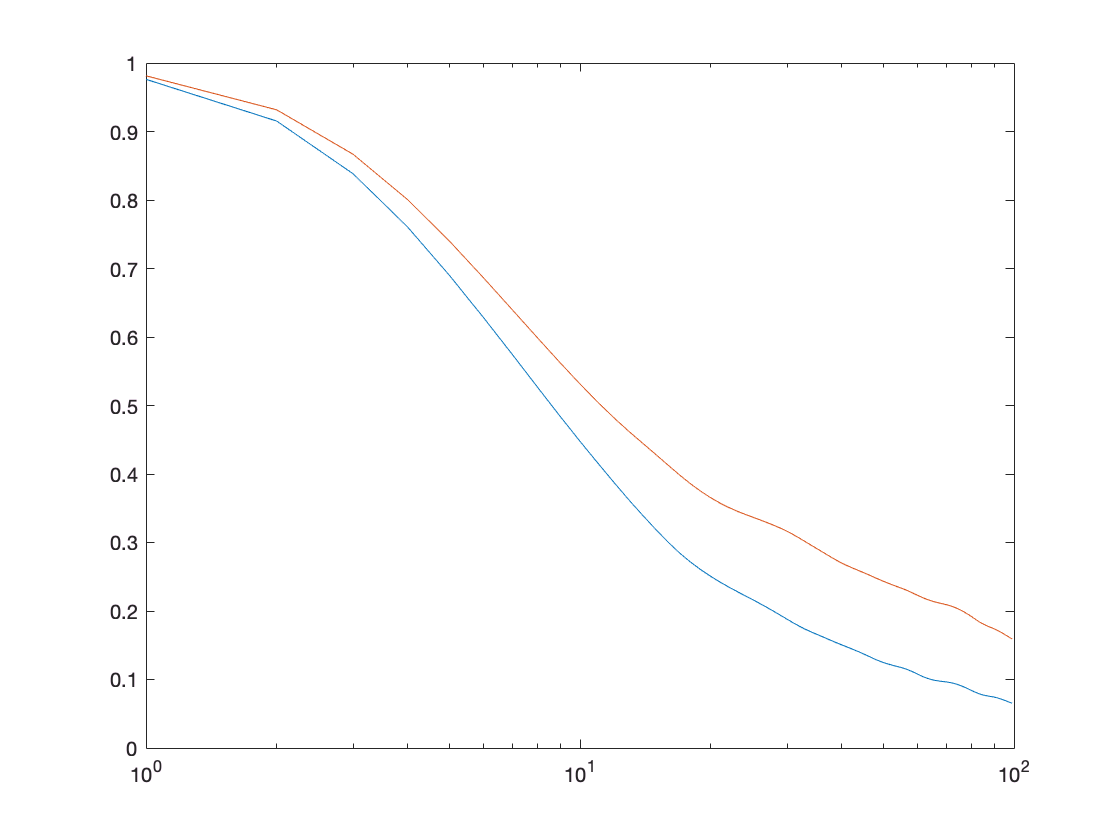

for i = 1:length(distance_class) 
    for j = 1:length(d) 
        for n = 1:500
                y = randsample(obs_pairs(j,i),obs_pairs(j,i),true);
    
                Mobs_bs(:,n,j,i) = memory_index(obs_sep(j,i).sep(y), 100);
                
        end
    end
end

[Mobsmean, Mobsci] = errbar4shaded(Mobs_bs); 


T = 0:99 ; 

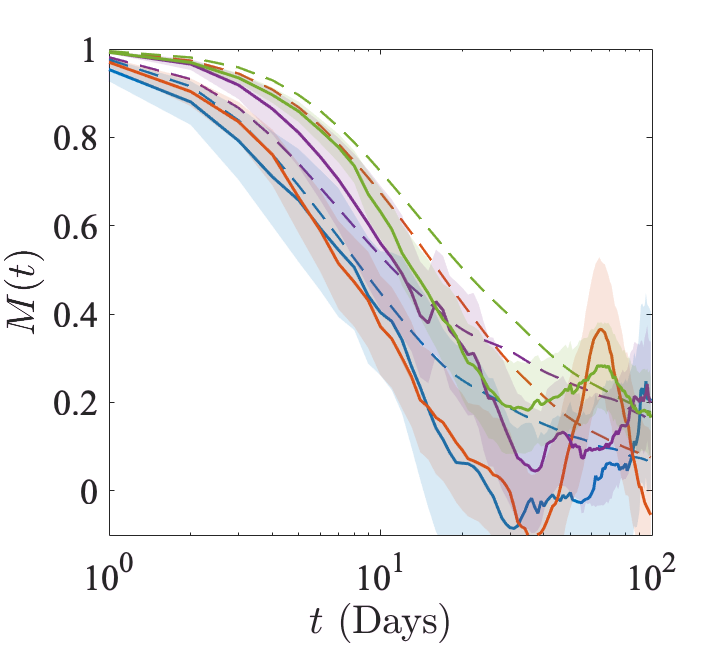

clear h g 

figure('unit','inches','pos',[0. 0. 5 4.5], 'renderer', 'OpenGl')
colors = get(gca, 'ColorOrder'); 
col_num = [1,4; 2, 5];

for i=1:length(distance_class)
    for j=1:length(d)
        g(j,i) = semilogx(T+0.001, Mmod(:,j,i),'--', 'color', colors(col_num(j,i),:),  'linewidth', 1.2);
        hold all 
    end
end

% shallow 
for i=1:length(distance_class)
    for j=1:length(d)
        h(j,i)= shadedErrorBar_semilogx(T+0.001, Mobsmean(:,j,i), Mobsci(:,:,j,i), ...
                    {'-','linewidth',1.5,'color',colors(col_num(j,i),:)},1);
    end
end
%h(2)= shadedErrorBar_semilogx(T+0.001, Mobsmean(:,2,i), Mobsci(:,:,2,i), ...
%    {'-','linewidth',1.5,'color',colors(col_num(2,i),:)},1);
              
                
axis([1 100 -0.1 1])
%legend([h(1).mainLine,h(2).mainLine, g(1), g(2)], ...
%    {'Obs 500-1000m', 'Obs 1000-1800m', 'Mod 750m', 'Mod 1500m'}, 'location', 'southwest','Fontsize',16) 

set(gca,'FontSize', 18, 'fontname','times')

xlabel('$t$ (Days)', 'Interpreter','Latex')
ylabel('$M (t)$' , 'Interpreter','Latex')

%print('memory_all.eps', '-depsc','-r400')


clear h g 

figure('unit','inches','pos',[0. 0. 5 4.5])
colors = get(gca, 'ColorOrder'); 
col_num = [1,4; 2, 5];

i=2

i = 2

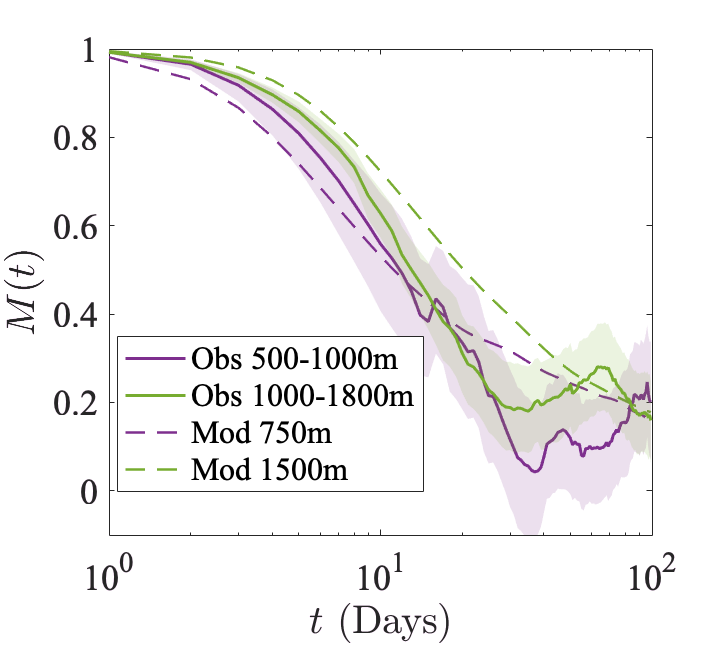

for j=1:length(d)
    g(j) = semilogx(T+0.001, Mmod(:,j,i),'--', 'color', colors(col_num(j,i),:),  'linewidth', 1.2);
    hold all 
end

% shallow 
h(1)= shadedErrorBar_semilogx(T+0.001, Mobsmean(:,1,i), Mobsci(:,:,1,i), ...
                    {'-','linewidth',1.5,'color',colors(col_num(1,i),:)},1);
hold all 
h(2)= shadedErrorBar_semilogx(T+0.001, Mobsmean(:,2,i), Mobsci(:,:,2,i), ...
                    {'-','linewidth',1.5,'color',colors(col_num(2,i),:)},1);

               
                
axis([1 100 -0.1 1])
legend([h(1).mainLine,h(2).mainLine, g(1), g(2)], ...
    {'Obs 500-1000m', 'Obs 1000-1800m', 'Mod 750m', 'Mod 1500m'}, 'location', 'best','Fontsize',16) 

set(gca,'FontSize', 18, 'fontname','times')

xlabel('$t$ (Days)', 'Interpreter','Latex')
ylabel('$M (t)$' , 'Interpreter','Latex')

%print('memory_30.eps', '-depsc','-r400')

for i =1:length(distance_class) 
    for j =1:length(d) 
        id = find(Mmod(:,j,i)<=0.6, 1) ; 
        Modtaum(j,i) = T(id);
        id = find(Mobsmean(:,j,i) <= 0.6, 1); 
        Obstaum(j,i) = T(id); 
    end
end

        

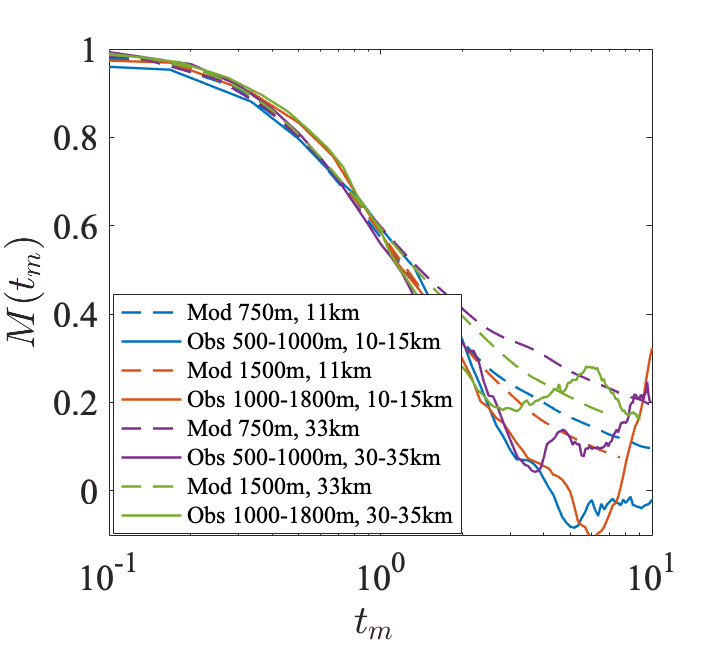

clear h g 

figure('unit','inches','pos',[0. 0. 5 4.5])
colors = get(gca, 'ColorOrder'); 
col_num = [1,4; 2, 5];

for i=1:length(distance_class)
    for j=1:length(d)
        g(j,i) = semilogx(T/Modtaum(j,i)+0.001, Mmod(:,j,i),'--', 'color', colors(col_num(j,i),:),  'linewidth', 1.2);
        hold all 
        h(j,i) = semilogx(T/Obstaum(j,i)+0.001, Mobsmean(:,j,i),'-', 'color', colors(col_num(j,i),:),  'linewidth', 1.2);
    end
end

legend({'Mod 750m, 11km','Obs 500-1000m, 10-15km', 'Mod 1500m, 11km','Obs 1000-1800m, 10-15km', ...
       'Mod 750m, 33km','Obs 500-1000m, 30-35km', 'Mod 1500m, 33km','Obs 1000-1800m, 30-35km'}, 'location', 'best', 'fontsize',12)

axis([0.1 10 -0.1 1])
set(gca,'FontSize', 18, 'fontname','times')

xlabel('$t_m$ ', 'Interpreter','Latex')
ylabel('$M (t_m)$' , 'Interpreter','Latex')
print('memory_comp_all.eps', '-depsc')

% dispersion
% model 
for i =1:length(distance_class)
    for j =1:length(d)       
            
            Mod_disp(j,i) = rel_disp(mod_sep(j,i).sep, ndays);
            
    end
end

% obs
for i =1:length(distance_class)
    for j =1:length(plevel)-1
        for n = 1:500
            y = randsample(obs_pairs(j,i),obs_pairs(j,i),true);
            Obsbs(n,j,i) = rel_disp(obs_sep(j,i).sep(y), ndays);
        end
    end
end

%% Convert from structures to arrays for simpler calcs.

for i =1:length(distance_class)
    for j =1:length(d)
        Moddisp(:,j,i) = Mod_disp(j,i).avdisp/1e6; 
        Moddisp_zon(:,j,i) = Mod_disp(j,i).avdispzon/1e6;
        Moddisp_mer(:,j,i) = Mod_disp(j,i).avdispmer/1e6;
    end
end

for i =1:length(distance_class)
    for j =1:length(plevel)-1
        for n=1:500 
            Obsdisp(:,n,j,i) = Obsbs(n,j,i).avdisp/1e6;
            Obsdisp_zon(:,n,j,i) = Obsbs(n,j,i).avdispzon/1e6;
            Obsdisp_mer(:,n,j,i) = Obsbs(n,j,i).avdispmer/1e6;
        end
    end
end

[Obsdisp_mean, Obsdisp_ci] = errbar4shaded(Obsdisp);
[Obsdisp_mean, Obsdisp_cilog] = errbar4shadedlog(Obsdisp);

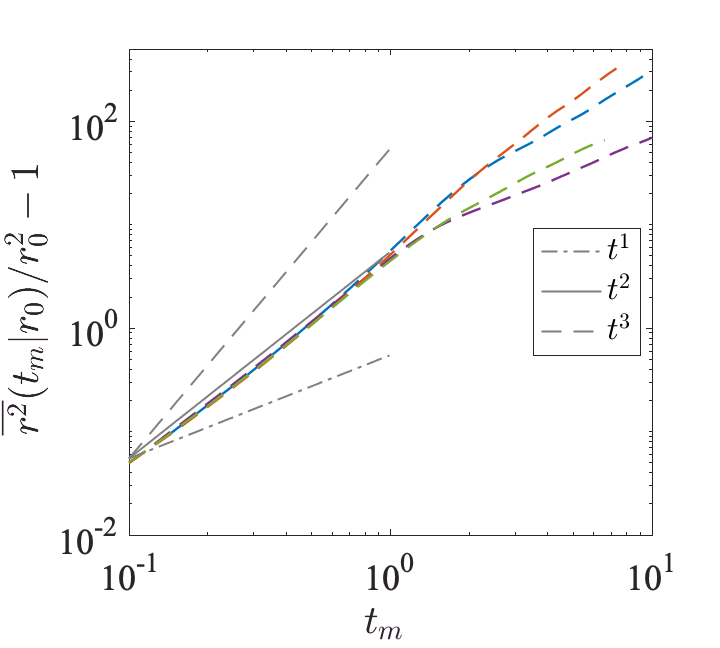

% Figure at first depth 
close all 
clear h g
figure('unit','inches','pos',[0. 0., 5, 4.5], 'renderer','painters')
for j= 1:length(d);
for i =1:length(distance_class)
    
    %h(i)= shadedErrorBar_log(T/Obstaum(j,i)+0.001, Obsdisp_mean(:,j,i)/ Obsdisp_mean(1,j,i) - 1, Obsdisp_cilog(:,:,j,i), ...
%                    {'-','linewidth',1.5,'color',colors(col_num(j,i),:)},1);
    %hold all
    g(i) = loglog(T/Modtaum(j,i), Moddisp(:,j,i)./ Moddisp(1,j,i) -1  , '--', 'color', colors(col_num(j,i),:), 'linewidth', 1.2);
    hold all
end
end 
Tax= T(5:100);
t1 = loglog(Tax/100, 5.5*10^-3*Tax.^1,'-.', 'color', [0.5 0.5 0.5], 'linewidth', 1.);
t2 = loglog(Tax/100, 5.5*10^-4*Tax.^2,'-', 'color', [0.5 0.5 0.5], 'linewidth', 1.);
t3 = loglog(Tax/100, 5.5*10^-5*Tax.^3,'--', 'color', [0.5 0.5 0.5], 'linewidth', 1.);
%t2 = loglog(Tax, 10^8.15*Tax.^2,'-.', 'color', [0.5 0.5 0.5]);
%t1 = loglog(Tax, 10^3.*Tax, 'color', [0.5 0.5 0.5], 'linewidth', 1.);

legend([t1, t2, t3] , {'$t^1$','$t^2$','$t^3$'}, 'Interpreter', 'Latex','Location', 'best')
%A = legend([h(1).mainLine,h(2).mainLine,  g, t3, t1], ...
%    {'Obs 10-15km', 'Obs 30-35km', 'Mod 11km', 'Mod 33km','~t^3','~t'},'location','best','fontsize',14); 
axis([0.1 10 1e-2 5e2])
%legend boxoff
%set(A, 'location','best')
%grid on
set(gca,'FontSize', 18,'fontname','times')
xlabel('$t_m$ ', 'Interpreter','Latex') 
ylabel('$\overline{r^2}(t_m | r_0)/r_0^2 - 1$ ', 'Interpreter','Latex')
print('ballistic_model.eps', '-depsc')

% Figure at first depth 
close all 
clear h g
figure('unit','inches','pos',[0. 0., 5, 4.5], 'renderer','painters')
for j= 1:length(d);
for i =1:length(distance_class)
    
    h(i)= loglog(T/Obstaum(j,i)+0.001, Obsdisp_mean(:,j,i)/ Obsdisp_mean(1,j,i)-1, ...
                    '-','linewidth',1.5,'color',colors(col_num(j,i),:));
    hold all
    %g(i) = loglog(T/Modtaum(j,i)+0.001, Moddisp(:,j,i)./ Moddisp(1,j,i) -1  , '--', 'color', colors(col_num(j,i),:), 'linewidth', 1.2);
    %hold all
end
end 
Tax= T(5:80);

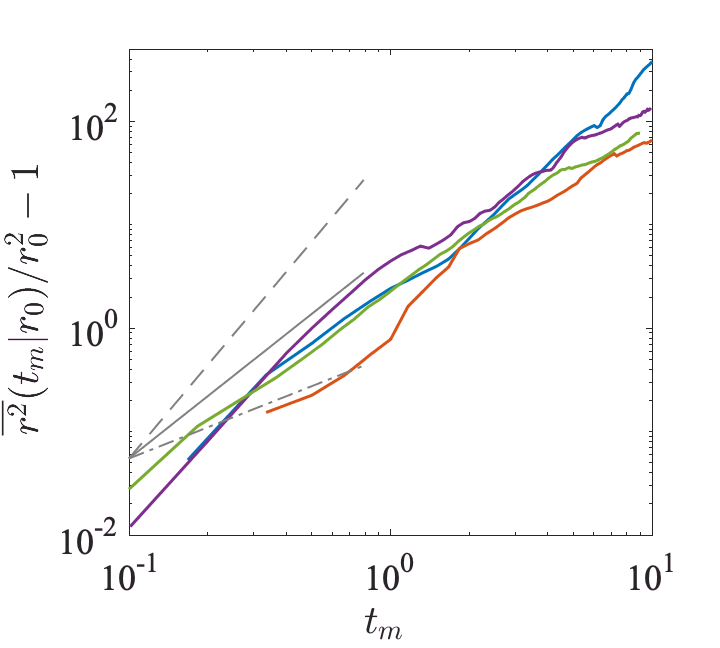

t1 = loglog(Tax/100, 5.5*10^-3*Tax.^1,'-.', 'color', [0.5 0.5 0.5], 'linewidth', 1.);
t2 = loglog(Tax/100, 5.5*10^-4*Tax.^2,'-', 'color', [0.5 0.5 0.5], 'linewidth', 1.);
t3 = loglog(Tax/100, 5.5*10^-5*Tax.^3,'--', 'color', [0.5 0.5 0.5], 'linewidth', 1.);
%t2 = loglog(Tax, 10^8.15*Tax.^2,'-.', 'color', [0.5 0.5 0.5]);
%t1 = loglog(Tax, 10^3.*Tax, 'color', [0.5 0.5 0.5], 'linewidth', 1.);


%A = legend([h(1).mainLine,h(2).mainLine,  g, t3, t1], ...
%    {'Obs 10-15km', 'Obs 30-35km', 'Mod 11km', 'Mod 33km','~t^3','~t'},'location','best','fontsize',14); 
axis([0.1 10 1e-2 5e2])
%legend boxoff
%set(A, 'location','best')
set(gca,'FontSize', 18,'fontname','times')
xlabel('$t_m$ ', 'Interpreter','Latex') 
ylabel('$\overline{r^2}(t_m | r_0)/r_0^2 - 1$ ', 'Interpreter','Latex')
print('ballistic_obs.eps', '-depsc')